# Segment Analyze

做segment对齐和标记

后面还要修改split的逻辑，根据标记来处理数据集

1. event/total

2. 计算delay（要不要先把中间空白的那一段剪掉？）（先不减，用全部算一次，再用不要前面一部分算一次，看看有没有很大区别owo？）

3. 计算response time

4. 标记需要训练的数据段，向前留出足够的history

5. check一下数据集长度

close all;clear;clc;
[M1, mPFC, ratios, eventTrain, M1num, mPFCnum, actTrain, segTrain, segRatios] = spikeTime2Train("data/data_rat010_0615_event.mat");

In all data

fprintf(['M1withSpike=%0.4f\nmPFCwithSpike=%0.4f\nM1multiSpike=%0.4f\n' ...
  'mPFCmultiSpike=%0.4f'], ratios)

M1withSpike=0.2069
mPFCwithSpike=0.1322
M1multiSpike=0.1154
mPFCmultiSpike=0.0669

Particularly, in segmented data

fprintf(['M1withSpike=%0.4f\nmPFCwithSpike=%0.4f\nM1multiSpike=%0.4f\n' ...
  'mPFCmultiSpike=%0.4f'], segRatios)

M1withSpike=0.2258
mPFCwithSpike=0.1411
M1multiSpike=0.1253
mPFCmultiSpike=0.0665

sum(eventTrain)

ans = 42192

sum(segTrain)

ans = 47614

successCount = 0;
spikeLength = length(eventTrain);
for i=2:spikeLength
  if (eventTrain(i-1) == 1 && eventTrain(i) == 0)
    successCount = successCount + 1;
  end
end
successCount

successCount = 164

responseTime = zeros(1,successCount);
trailNum = 1;
for i=2:spikeLength
  if (eventTrain(i-1) == 1 && eventTrain(i) == 0)
    trailNum = trailNum + 1;
  end
  if (eventTrain(i) == 1)
    responseTime(trailNum) = responseTime(trailNum) + 1;
  end
end
responseTime = responseTime/100;

response time大于6s的不要了

trailTooLong = find(responseTime>6);
eventTrainRow = eventTrain;
trailNum = 0;
for i=2:spikeLength
  if (eventTrainRow(i-1) == 0 && eventTrainRow(i) == 1)
    trailNum = trailNum + 1;
  end
  if (eventTrainRow(i) == 1 && ismember(trailNum, trailTooLong))
    eventTrain(i) = 0;
    segTrain(i) = 0;
  end
end

sum(eventTrain)

ans = 37234

sum(segTrain)

ans = 46742

successCountRow = successCount;
successCount = 0;
for i=2:spikeLength
  if (eventTrain(i-1) == 1 && eventTrain(i) == 0)
    successCount = successCount + 1;
  end
end
successCount

successCount = 157

responseTimeRow = responseTime;
responseTime = zeros(1,successCount);
trailNum = 1;
for i=2:spikeLength
  if (eventTrain(i-1) == 1 && eventTrain(i) == 0)
    trailNum = trailNum + 1;
  end
  if (eventTrain(i) == 1)
    responseTime(trailNum) = responseTime(trailNum) + 1;
  end
end
responseTime = responseTime/100;

Plot

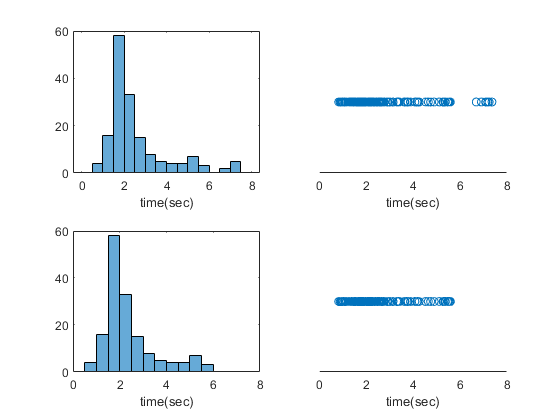

figure
subplot(2,2,1)
histogram(responseTimeRow, [0 0.5 1 1.5 2 2.5 3 3.5 4 4.5 5 5.5 6 6.5 7 7.5 8])
xlabel("time(sec)")
subplot(2,2,3)
histogram(responseTime)
xlabel("time(sec)")
xlim([0,8])
subplot(2,2,2)
scatter(responseTimeRow,zeros(1,successCountRow))
xlabel("time(sec)")
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca,'YColor','white')
subplot(2,2,4)
scatter(responseTime,zeros(1,successCount))
xlabel("time(sec)")
xlim([0,8])
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca,'YColor','white')

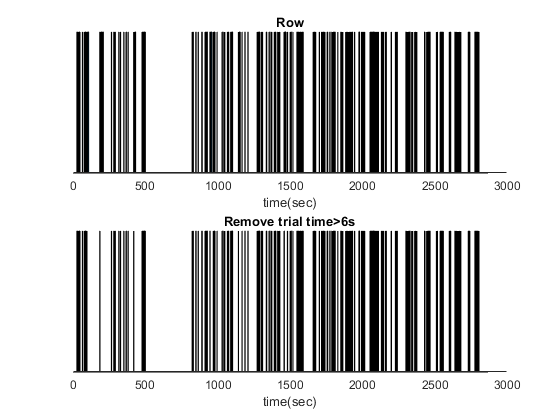

figure
subplot(2,1,1)
spikeLengthRow = length(eventTrainRow);
area(0.01:0.01:spikeLengthRow*0.01, eventTrainRow)
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca, 'YColor', 'white')
xlabel("time(sec)")
title('Row')
subplot(2,1,2)
spikeLength = length(eventTrain);
area(0.01:0.01:spikeLength*0.01, eventTrain)
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca, 'YColor', 'white')
xlabel("time(sec)")
title('Remove trial time>6s')

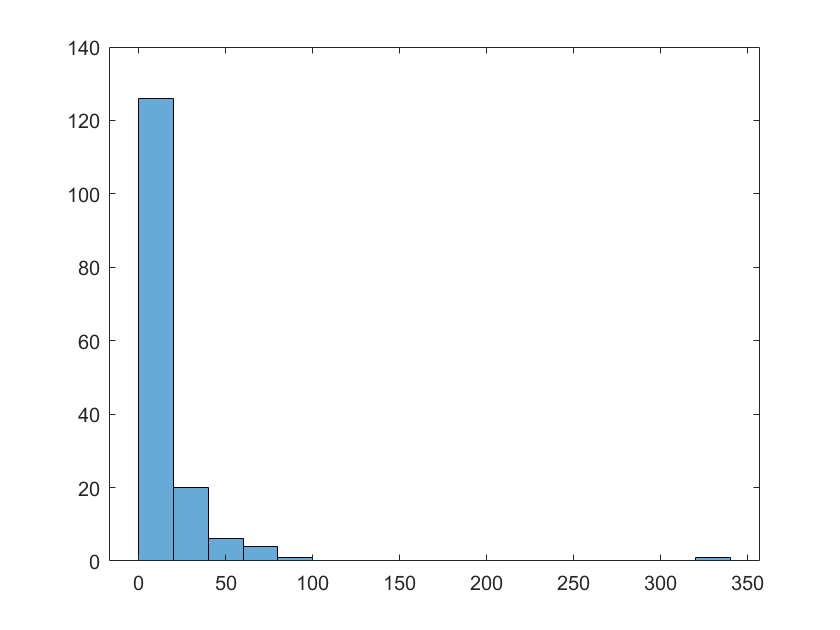

% 统计trail之间的事件，比较长的扔掉？或者直接只取trail前后一段比较长的事件，不管optimal delay了
emptyTime = zeros(1,successCount+1);
trailNum = 1;
emptyTime(1) = 1;
for i=2:spikeLength
  if (eventTrain(i)==0)
    emptyTime(trailNum) = emptyTime(trailNum)+1;
  end
  if (eventTrain(i-1) == 0 && eventTrain(i) == 1)
    trailNum = trailNum + 1;
  end
end
emptyTime = emptyTime/100;
figure
histogram(emptyTime)

计算delay，delay一个时间点，然后计算mutual information

takenBins = 82001:160000;
eventTrainPart = eventTrain(takenBins)';
actTrainPart = actTrain(takenBins)';
mPFCPart = mPFC(takenBins,:);
M1Part = M1(takenBins,:);

M1delayMI   = zeros(M1num, 101);
mPFCdelayMI = zeros(mPFCnum, 101);
for delay=-50:50 % delay vary from 0ms~700ms
  M1delayMI(:,delay+1+50) = mutualInformation(M1Part(1+50:end-delay-50,:), actTrainPart(delay+1+50:end-50));
  mPFCdelayMI(:,delay+1+50) = mutualInformation(mPFCPart(1+50:end-delay-50,:), M1Part(delay+1+50:end-50,2));
end

M1与actionTrain之间的delay在某几个neuron上很明显

actionTrain：把press和release动作前后100ms赋值为1，其余时间为0

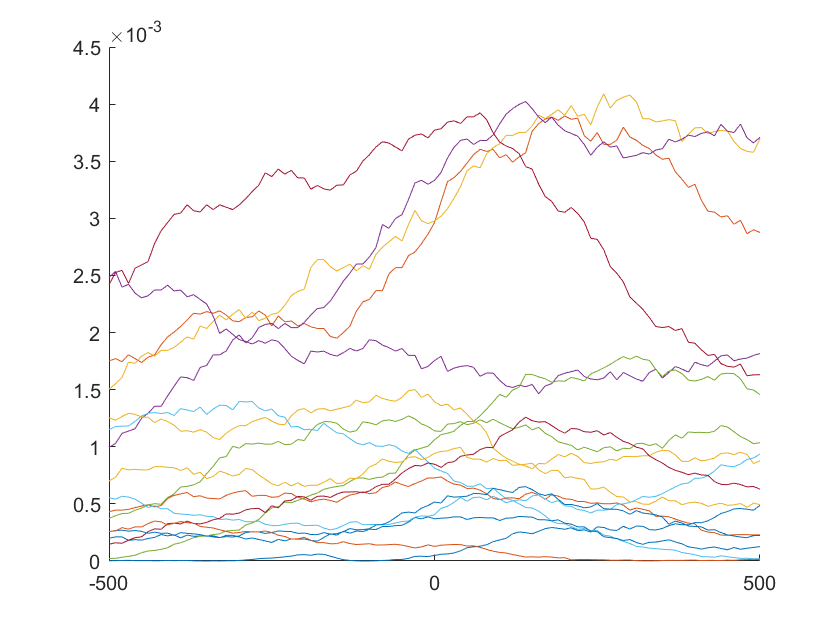

figure
hold on
for i=1:M1num
  plot(-500:10:500,M1delayMI(i,:))
end
hold off

其中[2 3 4 7 11 17]相对高

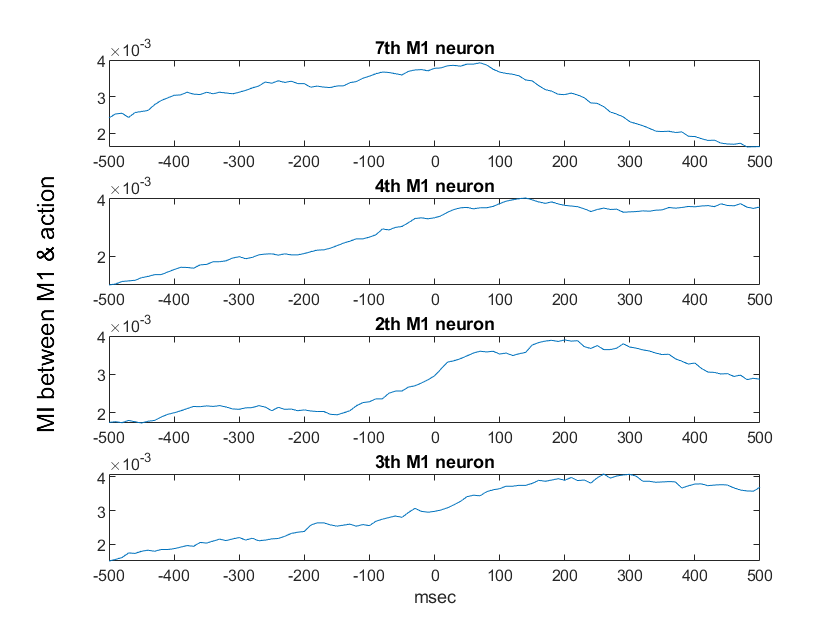

figure
for i=[7 4 2 3]
  subplot(4,1,find([7 4 2 3]==i))
  plot(-500:10:500, M1delayMI(i,:))
  title([num2str(i), 'th M1 neuron'])
end
xlabel("msec")
hAxis = axes('visible','off');
h = text(-0.1,0.5,'MI between M1 & action');
set(h,'fontsize',12,'rotation',90,'HorizontalAlignment','center')

mPFC和event之间似乎没有明显的delay关系

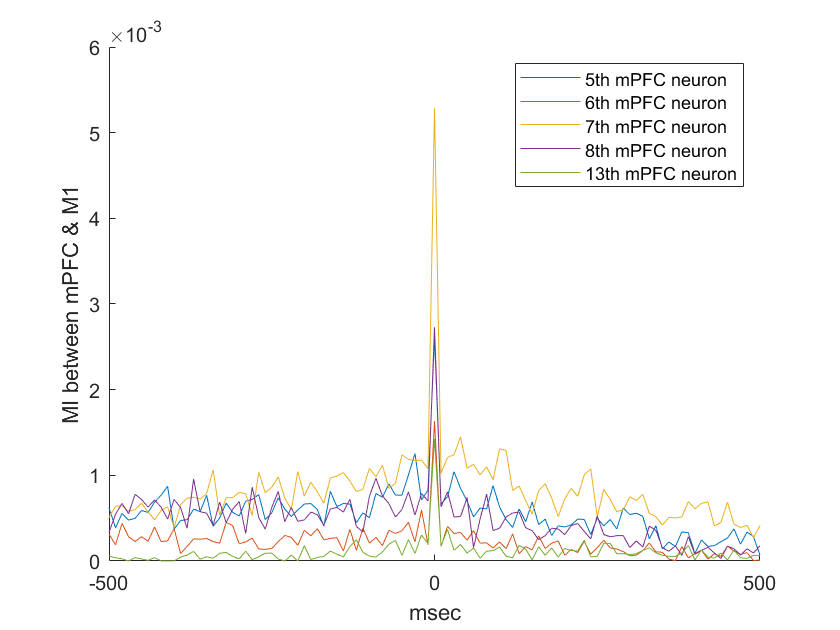

figure
hold on
for i=[5 6 7 8 13]
  plot(-500:10:500, mPFCdelayMI(i,:))
end
hold off
legend("5th mPFC neuron", "6th mPFC neuron", "7th mPFC neuron", "8th mPFC neuron", "13th mPFC neuron")
xlabel("msec")
ylabel("MI between mPFC & M1")

save some results

M1neurons   = [7 2 3];
mPFCneurons = [5 6 7 8 13];
recordRange = 1:281000;
M1spike = M1(recordRange, M1neurons);
mPFCspike = mPFC(recordRange, mPFCneurons);
eventTrain = eventTrain(recordRange);
segTrain = segTrain(recordRange);
optimalDelay = [find(M1delayMI(M1neurons(1),:)==max(M1delayMI(M1neurons(1),:))), find(M1delayMI(M1neurons(2),:)==max(M1delayMI(M1neurons(2),:))), find(M1delayMI(M1neurons(3),:)==max(M1delayMI(M1neurons(3),:)))]...
    -1-50;
% save("data/data_rat010_0615_spike_train_selected_with_delay.mat", "M1spike", "mPFCspike", "eventTrain", "optimalDelay", "segTrain")

load("data/data_rat010_0615_spike_train_selected_with_delay.mat")
M1index = 2;
[~,~,~,trainX,~,testX,trainY,~,testY,trainEvent,~,testEvent] = splitDataAdvance(1,mPFCspike,M1spike(:,M1index),eventTrain,optimalDelay(M1index),segTrain,1);
smoothedLambda = gaussianSmooth(trainY, 70);
bins = 1:length(trainY);
t=bins/100;
figure
subplot(2,1,1)
area(t, trainEvent(bins))
hold on
plot(t, smoothedLambda(bins)*5, 'r')
hold off
subplot(2,1,2)
plot(t, trainY(bins))

ccList = zeros(3,11);
for M1Idx=1:3
  [~,~,~,trainX,~,testX,trainY,~,testY,trainEvent,~,testEvent] = splitDataAdvance(1,mPFCspike,M1spike(:,M1Idx),eventTrain,optimalDelay(M1Idx),segTrain,1);
  for kernelSize=0:10
    cc=corrcoef(gaussianSmooth(trainY, kernelSize*10), trainEvent');
    cc=cc(2);
    ccList(M1Idx,kernelSize+1)=cc;
  end
end
plot(ccList')
legend("1", "2", "3")

partX = trainX(:,1);
smoothedLambda = gaussianSmooth(partX, 50);
bins = 4000:8000;
t=40:0.01:80;
figure
subplot(2,1,1)
area(t, trainEvent(bins))
hold on
plot(t, smoothedLambda(bins)*10)
hold off
subplot(2,1,2)
plot(t, partX(bins))